filelist =["data_01-Apr-2025_15-56-19.mat"
"data_01-Apr-2025_16-06-34.mat"
"data_01-Apr-2025_16-30-31.mat"  
]

filelist = 3×1 string array
    "data_01-Apr-2025_15-56-19.mat"
    "data_01-Apr-2025_16-06-34.mat"
    "data_01-Apr-2025_16-30-31.mat"




for exp_id =1:length(filelist)
    filename = "lab4/data/"+filelist(exp_id);
    data = load(filename).data;
    t = data(1,:);
    y = data(2,:);
    u = data(6,:);
    if exp_id==1
        exp = iddata(y',u',1/500);
    else
        exp_t = iddata(y',u',1/500);
        exp = merge(exp,exp_t);
    end
end


tf_sm0 = tfest(exp,2,0)


tf_sm0 =
 
  From input "u1" to output "y1":
          -27.9
  ---------------------
  s^2 + 23.62 s + 14.91
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "exp". 
Fit to estimation data: [63.09 34.35 67.28]%     
FPE: 0.001079, MSE: [0.001017 0.0005948 0.001099]
 
Model Properties


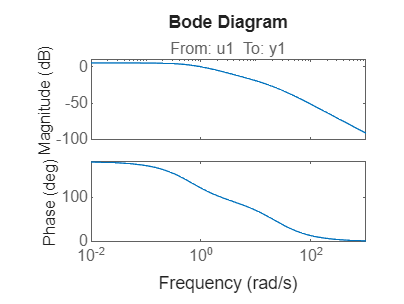

bodeplot(tf_sm0)